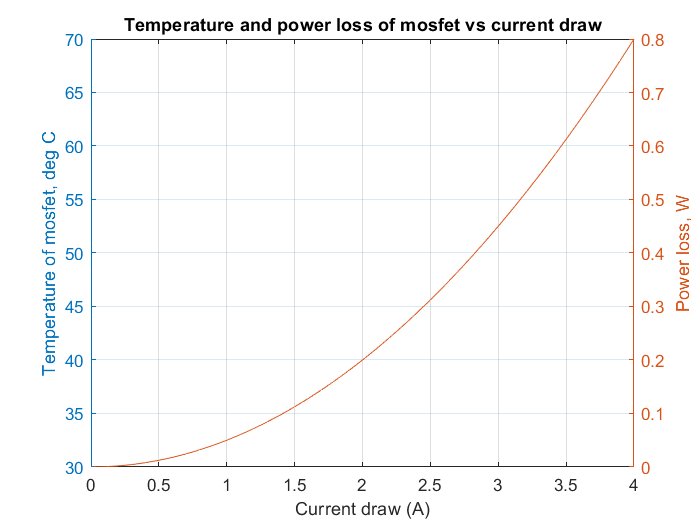

%mosfet calculations
max_current = 4;
RDS_ON = 0.05;
thermal_resistance = 50;
ambient = 30;
mosfet_current = 0:0.1:max_current;
power_loss = mosfet_current.^2 * RDS_ON;
thermal_change = thermal_resistance * power_loss;
hot_temp = ambient + thermal_change;
voltage_drop = mosfet_current * RDS_ON;
yyaxis left
plot(mosfet_current, hot_temp)
ylabel("Temperature of mosfet, deg C")
xlabel("Current draw (A)")
hold on
yyaxis  right
plot(mosfet_current, power_loss)
ylabel("Power loss, W")
title("Temperature and power loss of mosfet vs current draw")
grid on
hold off


%switching time estimate
gate_resistor = 300;
logic_voltage = 3.3;
gate_charge = 15 * 10^-9;
fraction_on_time_is_switching = 1/100;
gate_current = logic_voltage/gate_resistor;
gate_current_mA = gate_current * 1000

gate_current_mA = 11

charge_time_estimate = gate_charge/gate_current

charge_time_estimate = 1.3636e-06

recommended_max_drive_frequency_kHz = 1/charge_time_estimate / 10^3 * fraction_on_time_is_switching

recommended_max_drive_frequency_kHz = 7.3333

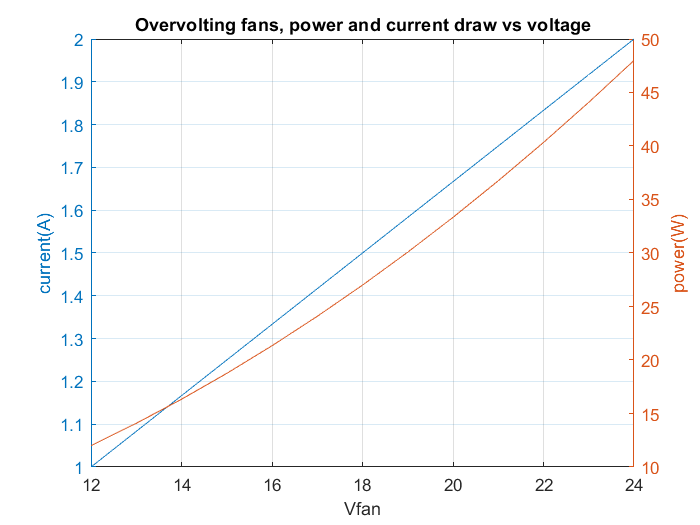

%overclocking fans

stock_voltage = 12;
stock_current = 1;
r_eq = stock_voltage/stock_current;
v_new = stock_voltage:1:(2*stock_voltage);
figure
yyaxis left
plot(v_new, v_new/r_eq);
xlabel("Vfan");
ylabel("current(A)")
yyaxis right
plot(v_new, v_new .^2 / r_eq)
xlabel("Vfan")
ylabel("power(W)")
grid on
title("Overvolting fans, power and current draw vs voltage")

%resistor calculations
V_max = [48 12 5 3.3 24 48]';
v_led = 3;
led_current = .01;
resistor_recommended = (V_max-v_led)/led_current;
power_disspation_resistor = (V_max - v_led) * led_current;
package_size = (0402 * (power_resistor < 1/16) + 1210 * (power_resistor > 1/10) + 0603 * and((power_resistor > 1/16) ,(power_resistor < 1/10)))';
T = table(V_max, resistor_recommended, power_disspation_resistor, package_size)

T = 6×4 table
    V_max    resistor_recommended    power_disspation_resistor    package_size
    _____    ____________________    _________________________    ____________

      48             4500                       0.45                  1210    
      12              900                       0.09                   603    
       5              200                       0.02                   402    
     3.3               30                      0.003                   402    
      24             2100                       0.21                  1210    
      48             4500                       0.45                  1210    


%Calculation for the current limiting resistor with the indicator LED for
%high voltage rails
V_1 = 24;
V_2 = 60;
V_f = 3;
I_max = .008;
R = V_2/I_max

R = 7500

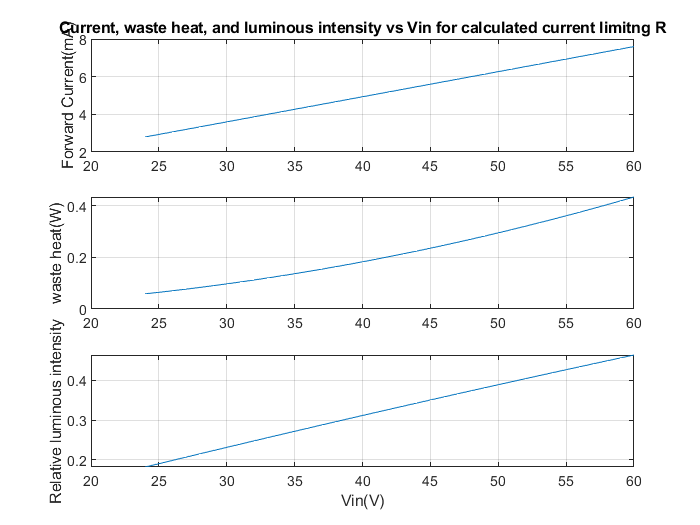

V_plot = 24:60;
I_plot = (V_plot-V_f)/R;
heat_output = (V_plot-V_f) .* I_plot;

tiledlayout(3,1)
nexttile
plot(V_plot, I_plot * 1000);
title("Current, waste heat, and luminous intensity vs Vin for calculated current limitng R")
ylabel('Forward Current(mA)');
grid on;
nexttile
plot(V_plot,heat_output)
ylabel("waste heat(W)");
grid on

%luminous intensity curve
forward_current = 10 ^ (-3) * [0 5 10 15 20]';
luminous_intensity = [0 0.32 0.586 0.834 1.029]';
f=fit(forward_current,luminous_intensity,'poly2');
intensity_plot = f(I_plot);
nexttile
plot(V_plot, intensity_plot)
ylabel("Relative luminous intensity")
xlabel("Vin(V)")
grid on